Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Digital Signal Processing Laboratory Experiment - 8**

% making the value of heaviside() at origin equal to 1
sympref('HeavisideAtOrigin', 1);
u = @(n) heaviside(n);

% defining the DTFT function
dtft = @(xn, n, w) xn * exp(-1j .* (n' * w));

% defining discrete time Inverse Fourier Transform
dtift = @(Xw, w, n) (Xw * exp(1j .* (w' * n))) ./ length(w);

% defining range of frequencies (omega) from -pi to +pi
w = -pi:0.01:pi;
omega_labels = ["-\pi", "-3\pi/4", "-\pi/2", "-\pi/4", 0, "\pi/4", "\pi/2", "3\pi/4", "\pi"];

Q1:


$$H(z) = \frac{1 \pm z^{-L}}{2}$$


Replacing $z$ by $e^{j\omega}$,


$$H(j\omega) = \frac{1 \pm e^{-j\omega L}}{2}$$


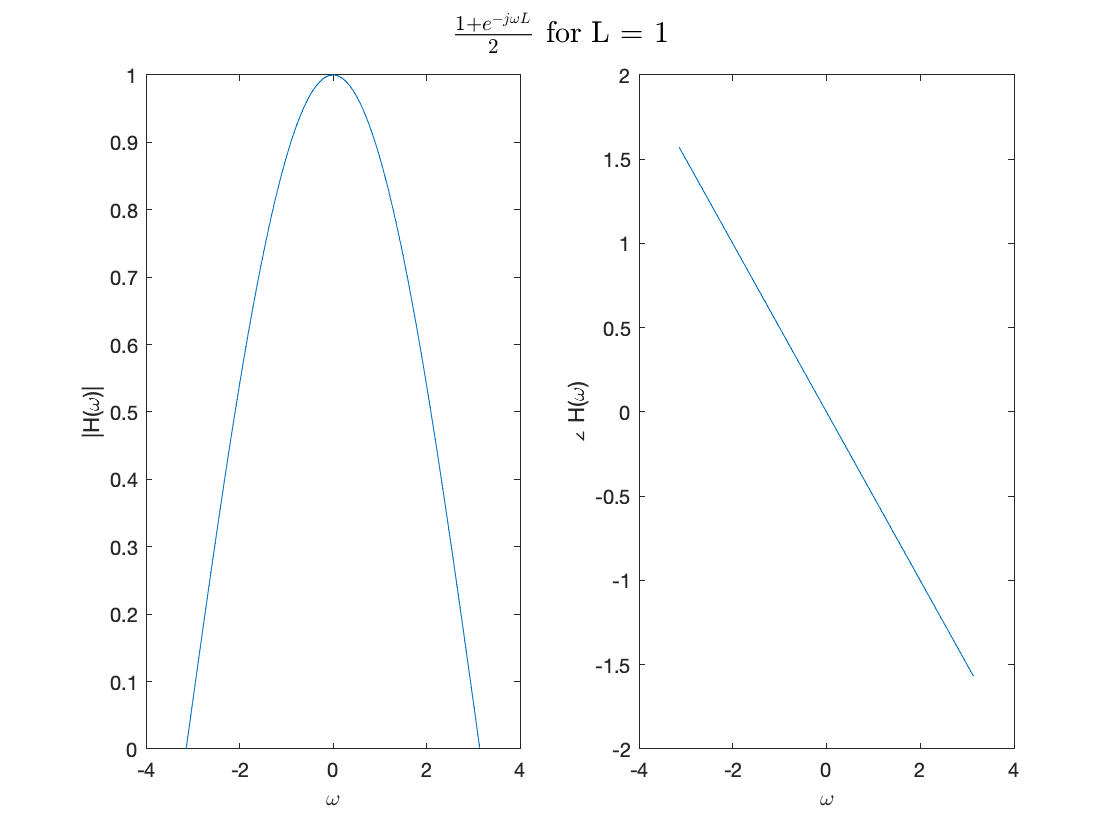

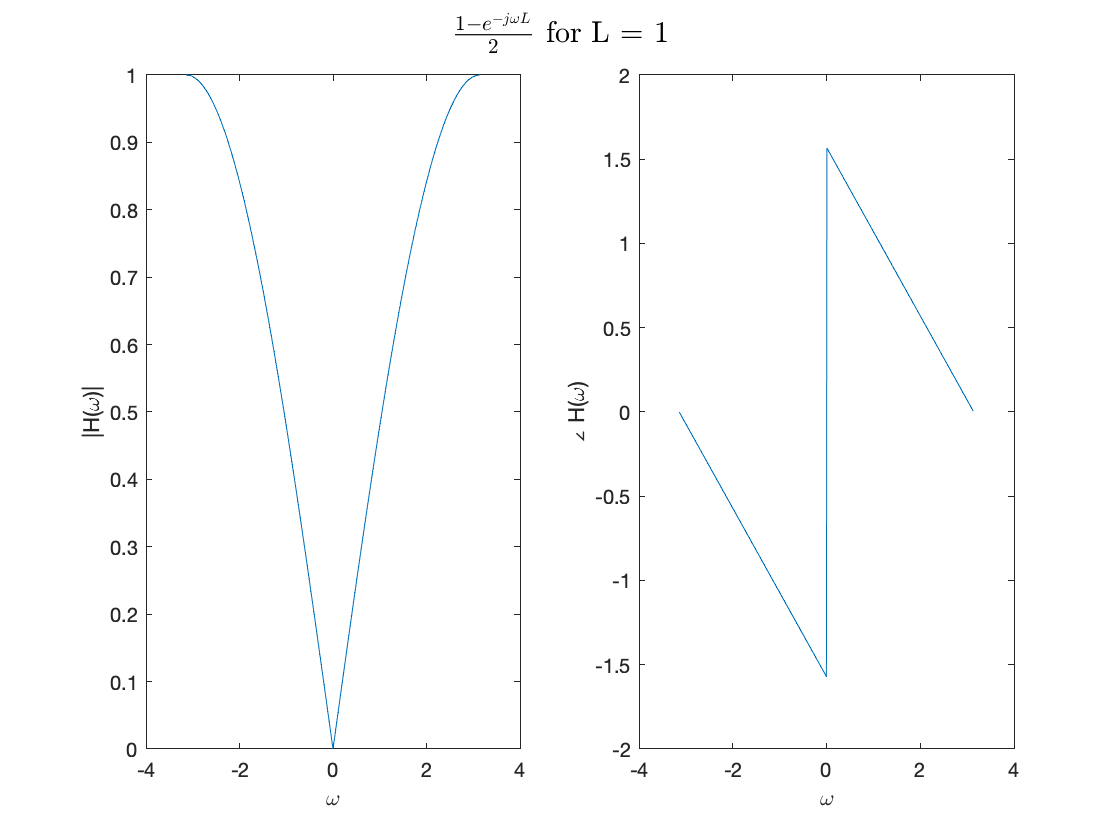

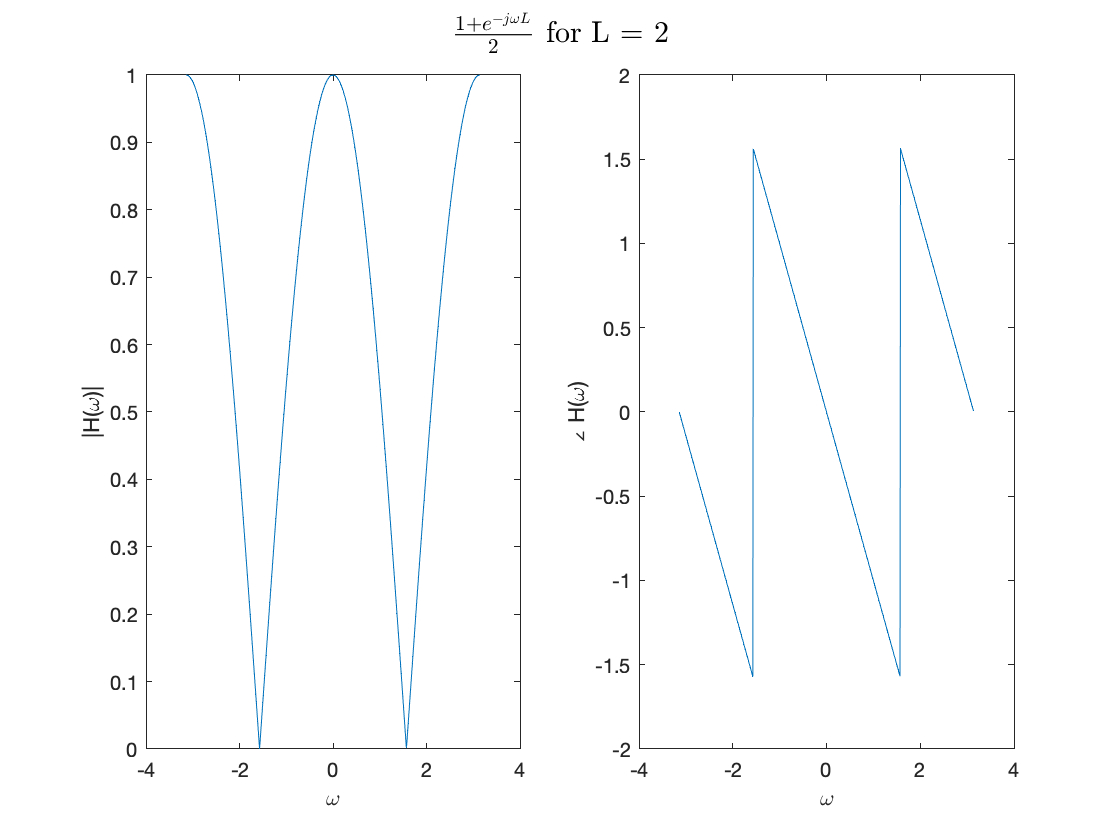

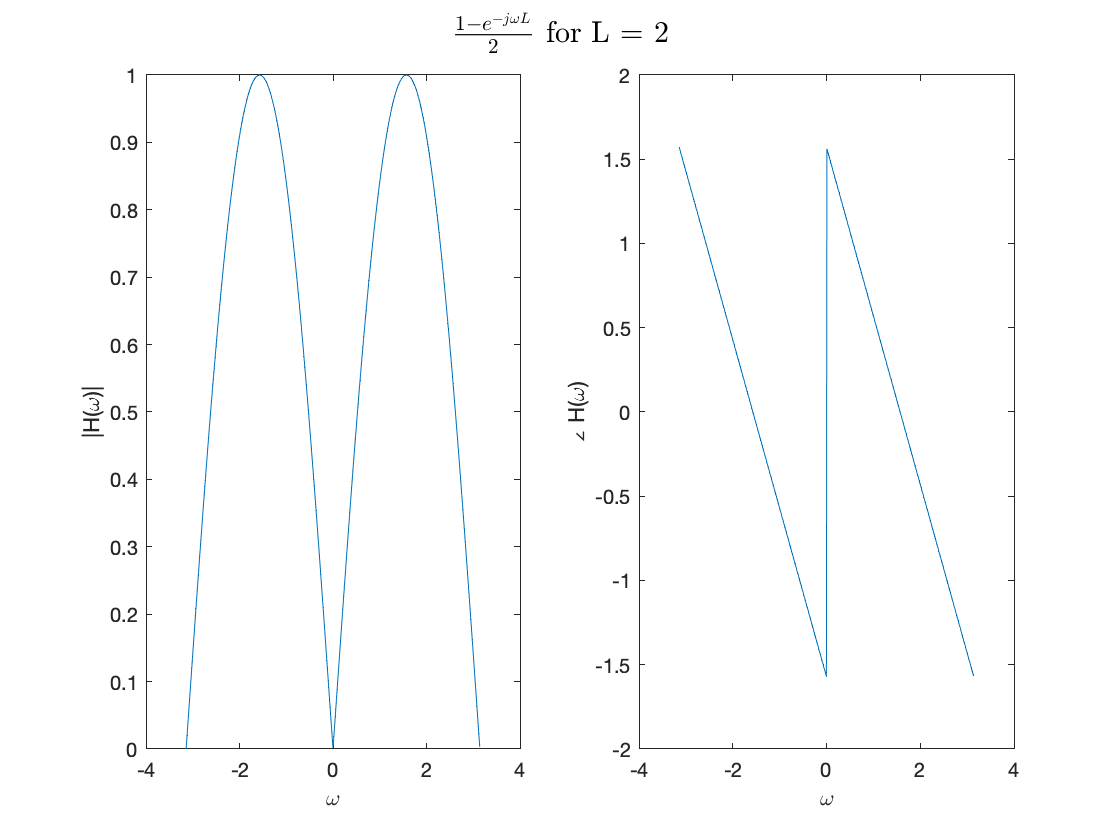

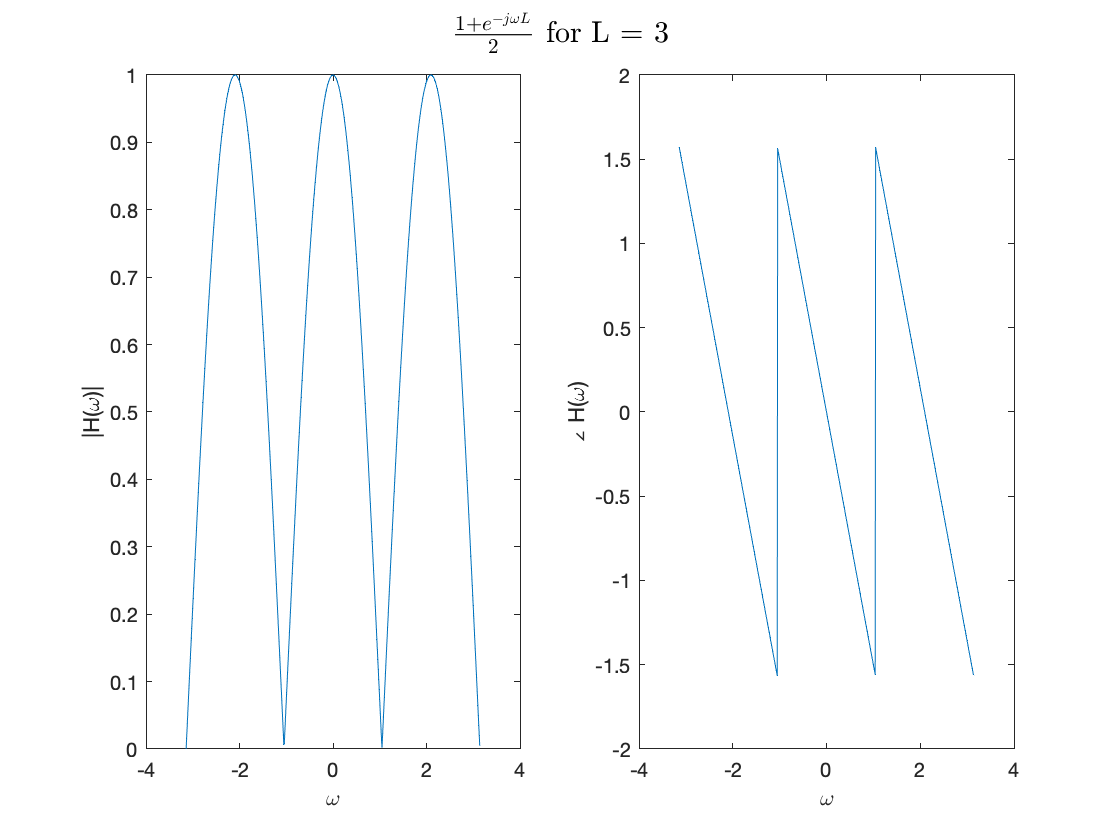

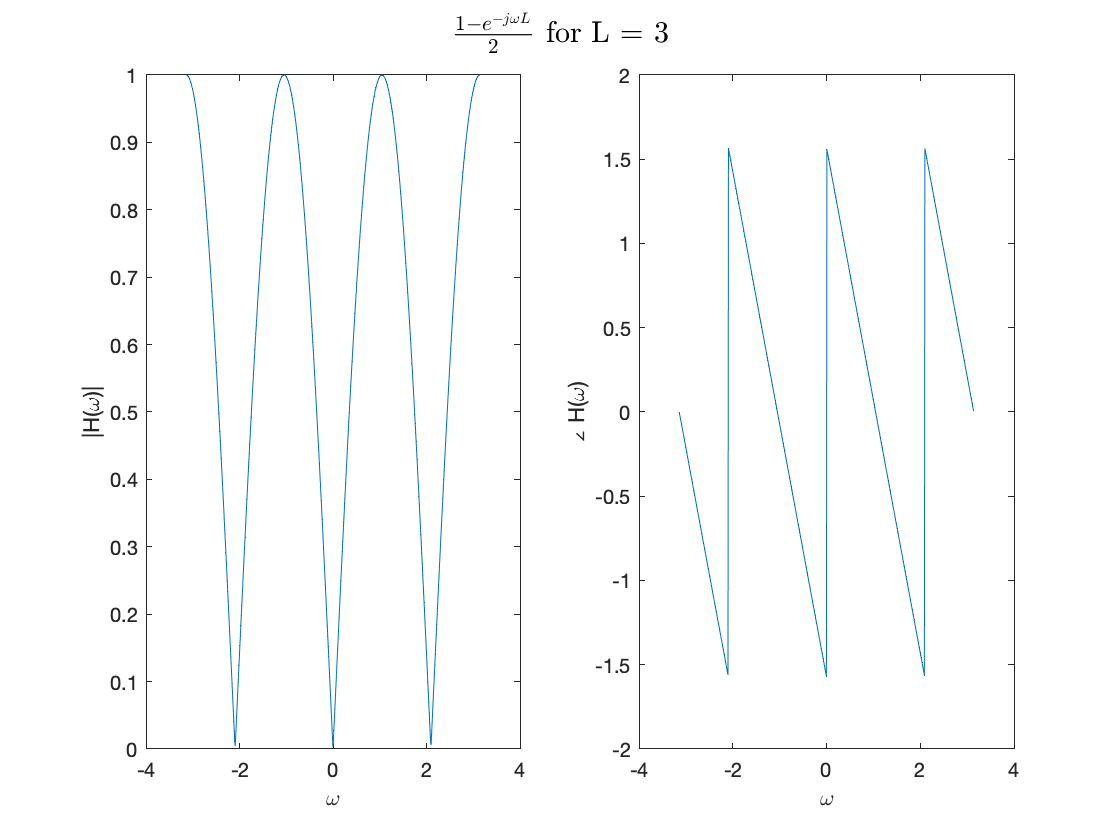

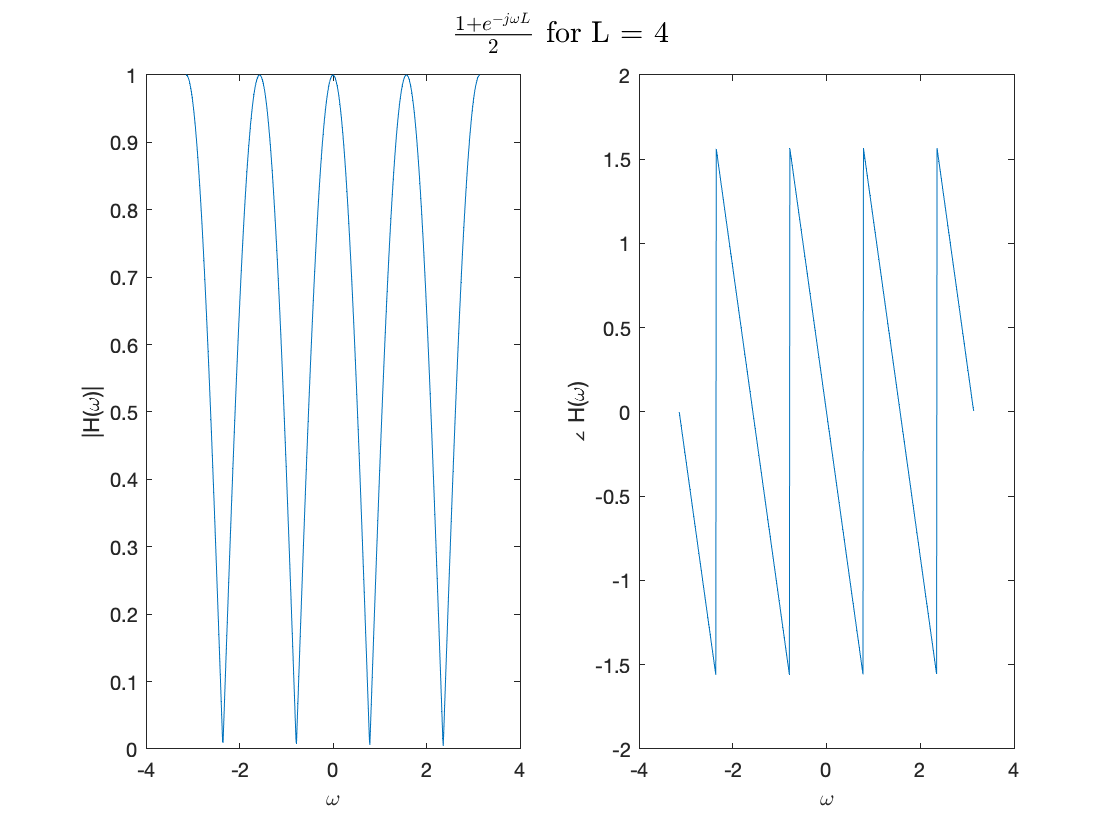

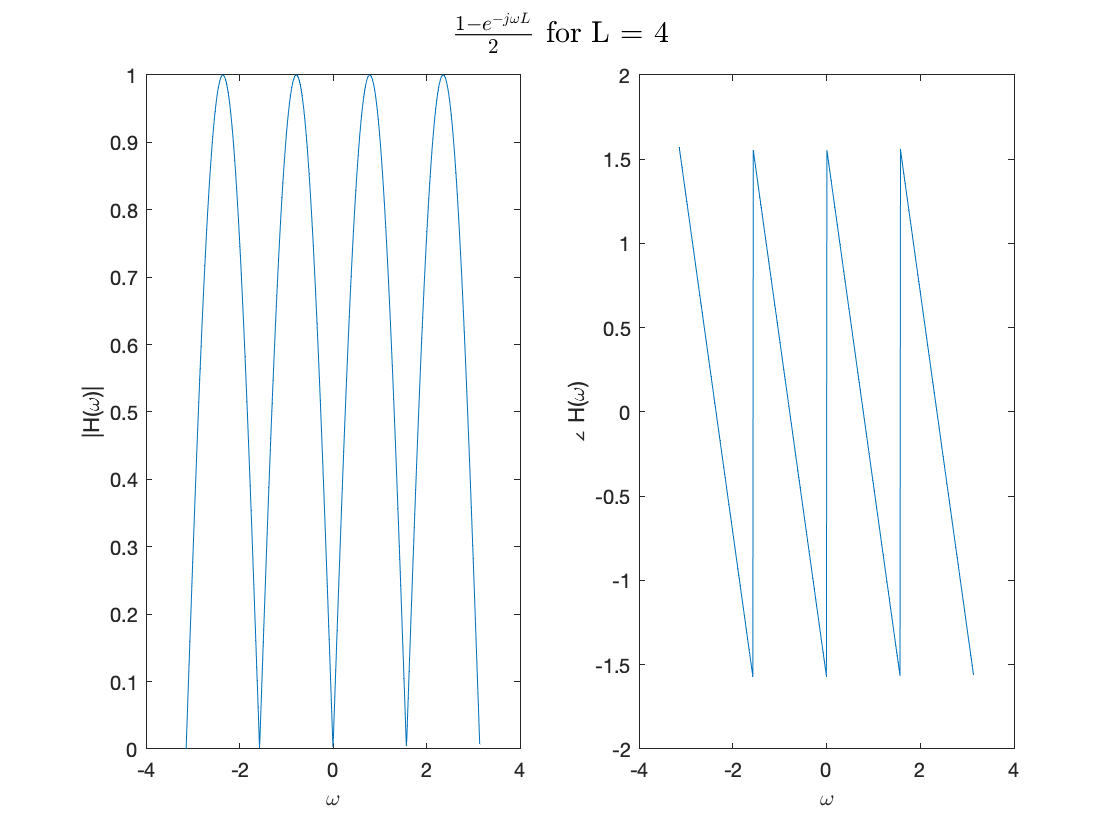

% (a), (b)
L_values = [1, 2, 3, 4];
for i = 1:length(L_values)
    L = L_values(i);
    H1 = (1 + exp(-1j .* w .* L)) ./ 2;
    H2 = (1 - exp(-1j .* w .* L)) ./ 2;
    
    figure;
    subplot(1, 2, 1);
    plot(w, abs(H1));
    xlabel("\omega"); ylabel("|H(\omega)|");
    subplot(1, 2, 2);
    plot(w, angle(H1));
    xlabel("\omega"); ylabel("\angle H(\omega)");
    sgtitle("$\frac{1 + e^{-j\omega L}}{2}$ for L = " + L, "Interpreter", "latex");
    
    figure;
    subplot(1, 2, 1);
    plot(w, abs(H2));
    xlabel("\omega"); ylabel("|H(\omega)|");
    subplot(1, 2, 2);
    plot(w, angle(H2));
    xlabel("\omega"); ylabel("\angle H(\omega)");
    sgtitle("$\frac{1 - e^{-j\omega L}}{2}$ for L = " + L, "Interpreter", "latex");
end

(c)

Q2:


$$H(z) = \left(\frac{1 - \alpha}{2}\right)\cdot \left(\frac{1-z^{-2}}{1 - \beta(1 + \alpha)z^{-1} + \alpha z^{-2}}\right)$$


Replacing $z$ by $e^{j\omega}$,


$$H(e^{j\omega}) = \left(\frac{1 - \alpha}{2}\right)\cdot \left(\frac{1-e^{-j2\omega}}{1 - \beta(1 + \alpha)e^{-j\omega} + \alpha e^{-j2\omega}}\right)$$


% (a)
H = @(a, b) ((1-a)/2) .* ((1 - exp(-2j.*w)) ./ (1 - b.*(1+a).*exp(-1j.*w) + a.*exp(-2j.*w)));

alpha_values = [1, 2, 3];
beta_values = [-1, 0, 1];
n = length(alpha_values);
m = length(beta_values)

m = 3

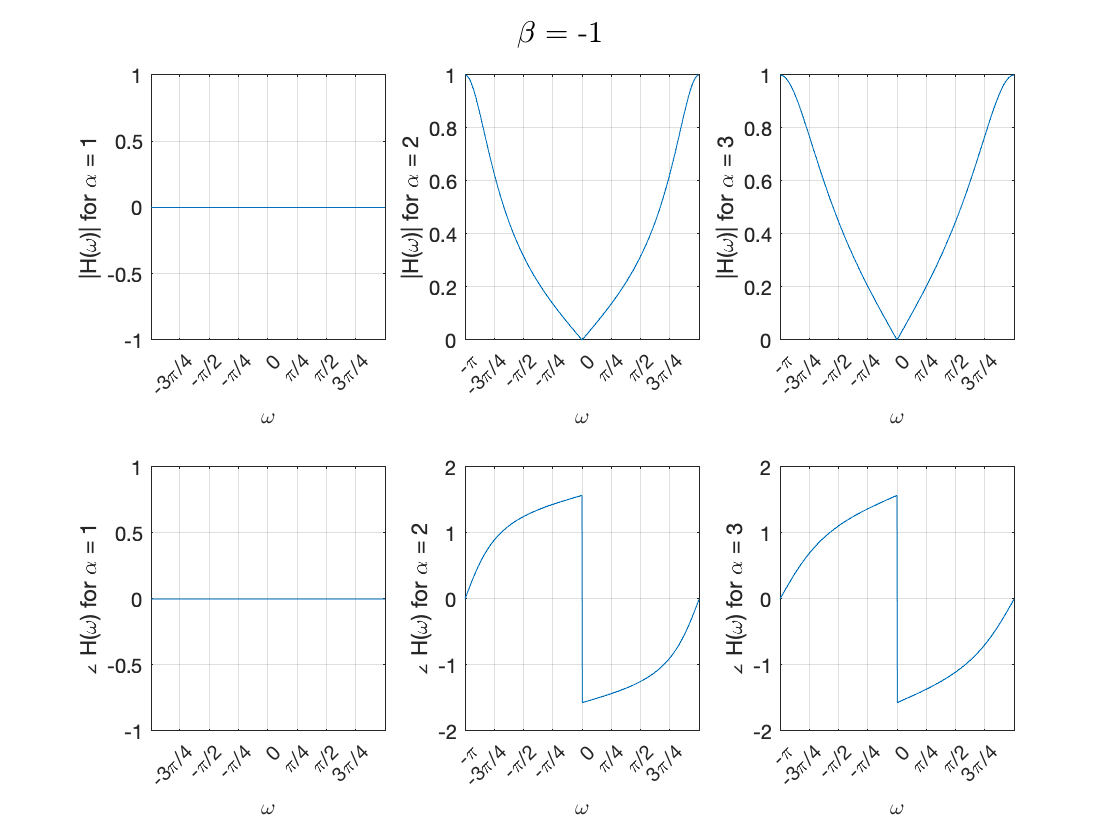

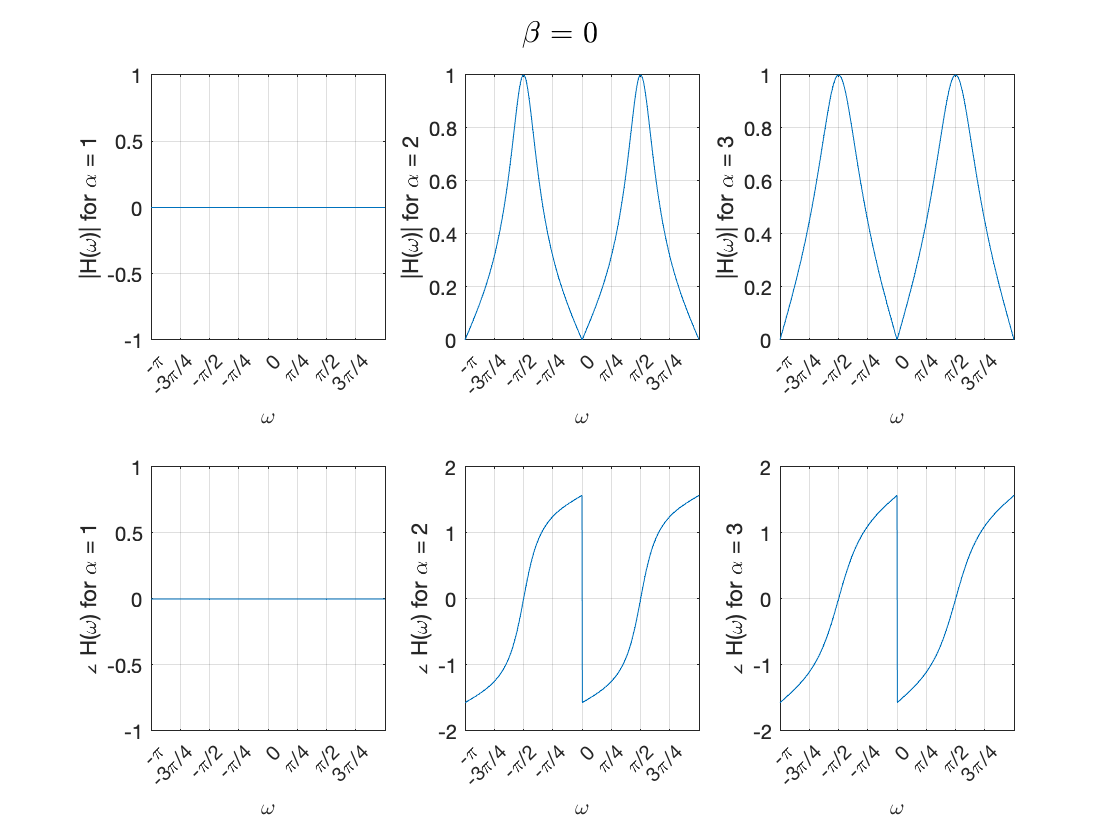

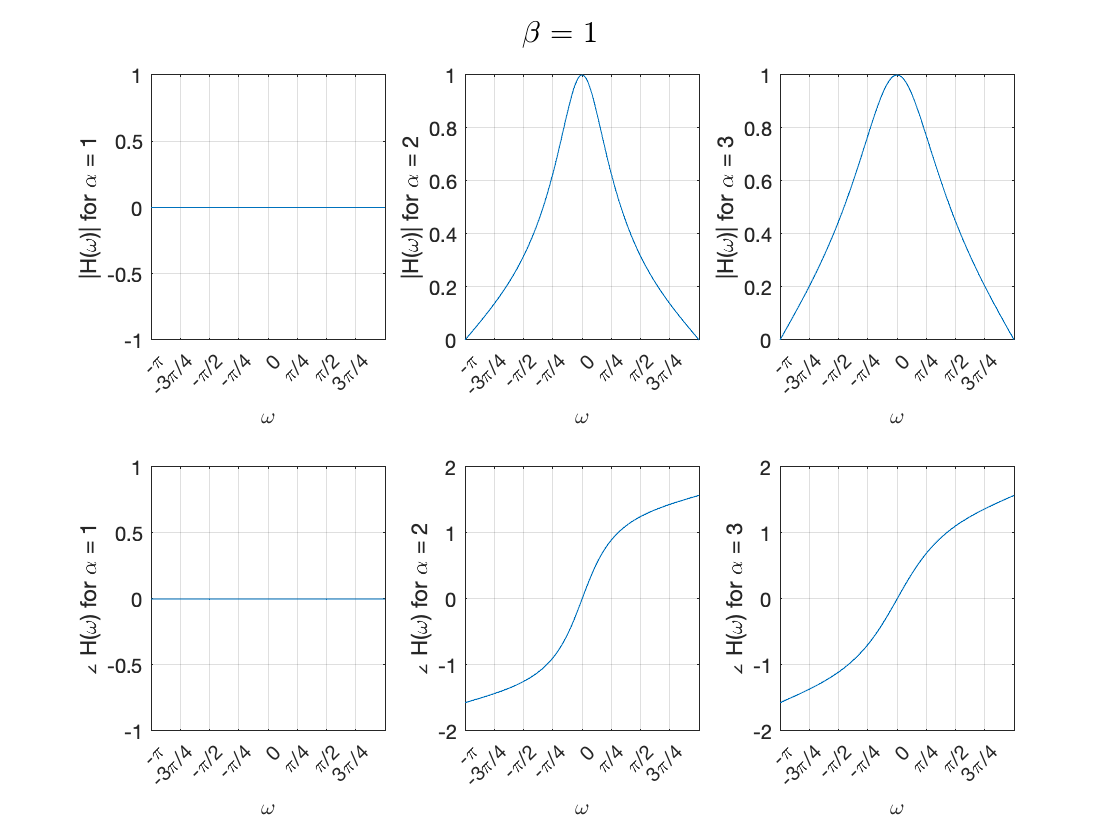


for i = 1:m
    figure;
    beta = beta_values(i);
    for j = 1:n
        alpha = alpha_values(j);
        Hw = H(alpha, beta);
        
        subplot(2, n, j);
        plot(w, abs(Hw));
        xlabel("\omega"); ylabel("|H(\omega)| for \alpha = " + alpha);
        xticks(-pi:pi/4:pi); xticklabels(omega_labels); grid();
        
        subplot(2, n, j + n);
        plot(w, angle(Hw));
        xlabel("\omega"); ylabel("\angle H(\omega) for \alpha = " + alpha);
        xticks(-pi:pi/4:pi); xticklabels(omega_labels); grid();
    end
    sgtitle("$\beta$ = " + beta, "Interpreter", "latex");
end

(b)

Q3:


$$y[n] = -6.76x[n] + 17.45x[n-1] -6.76x[n-2]$$


Taking the z-transform on both sides,


$$Y(z) = X(z)\cdot(-6.76 + 17.45z^{-1} -6.76z^{-2})$$



$$H(z) = \frac{Y(z)}{X(z)} = -6.76 + 17.45z^{-1} -6.76z^{-2}$$


Replacing $z$ by $e^{j\omega}$,


$$\Rightarrow H(j\omega) = -6.76 + 17.45e^{-j\omega} -6.76e^{-j2\omega}$$


Hw = -6.76 + 17.45.*exp(-1j.*w) -6.76.*exp(-2j.*w);
Hw2 = w ./ w;

x1 = @(n) cos(0.1.*n) + cos(0.4.*n);
x2 = @(omega, n) cos(omega.*n);
omega_values = [pi/4, pi/3, pi/2];
omega_val_strings = ["\pi/4", "\pi/3", "\pi/2"];

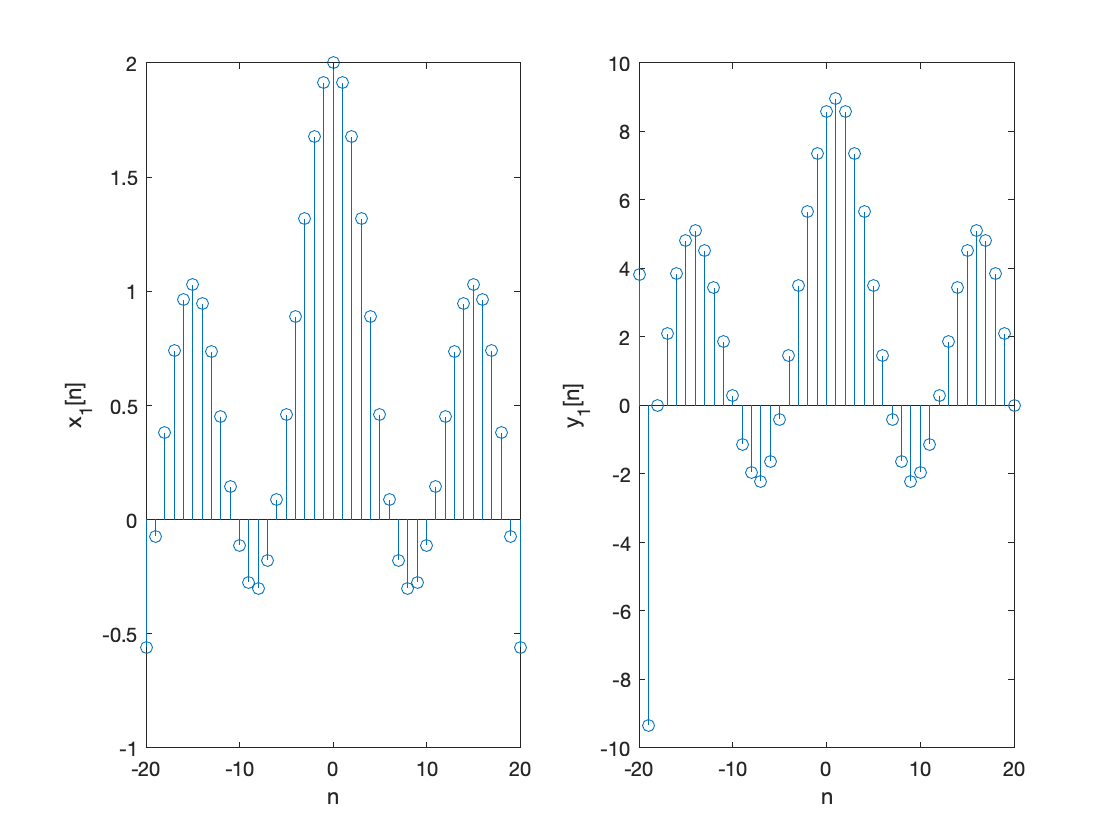

% (a)
n = -20:20;

x1n = x1(n);
y1n = real(dtift(dtft(x1n, n, w) .* Hw, w, n));
figure;
subplot(1, 2, 1);
stem(n, x1n);
xlabel("n"); ylabel("x_1[n]");
subplot(1, 2, 2);
stem(n, y1n);
xlabel("n"); ylabel("y_1[n]");

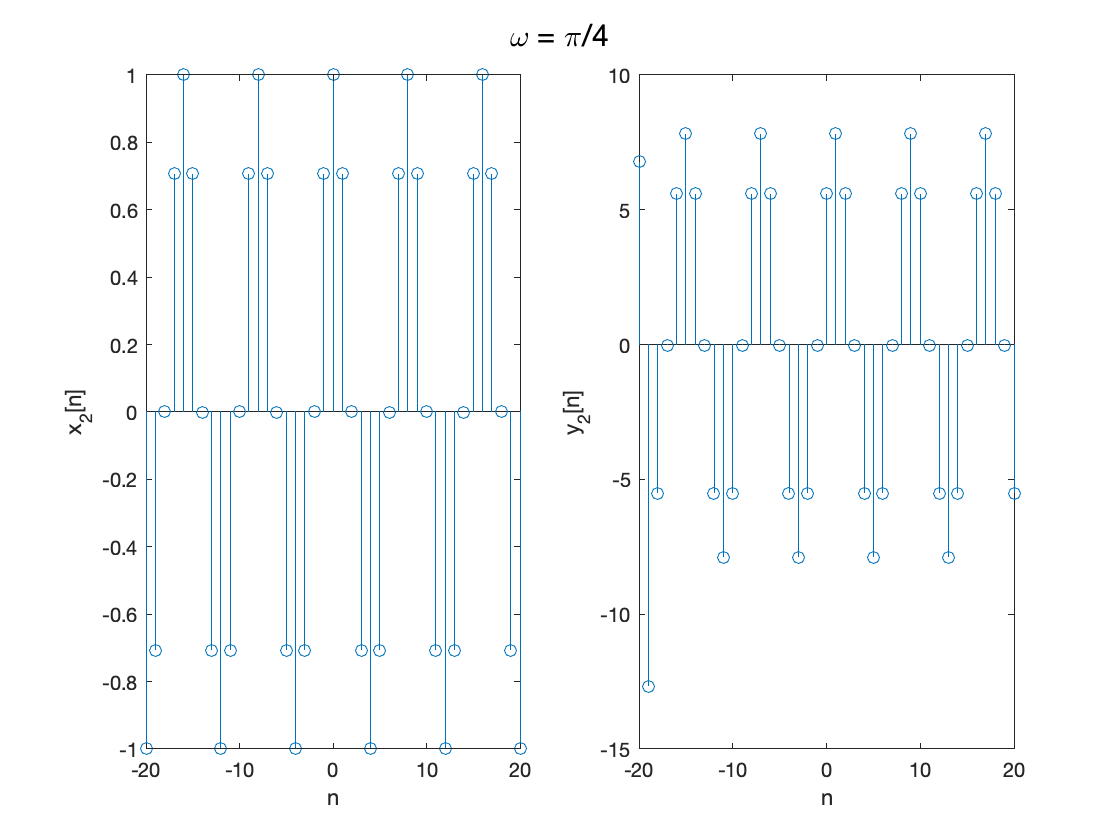

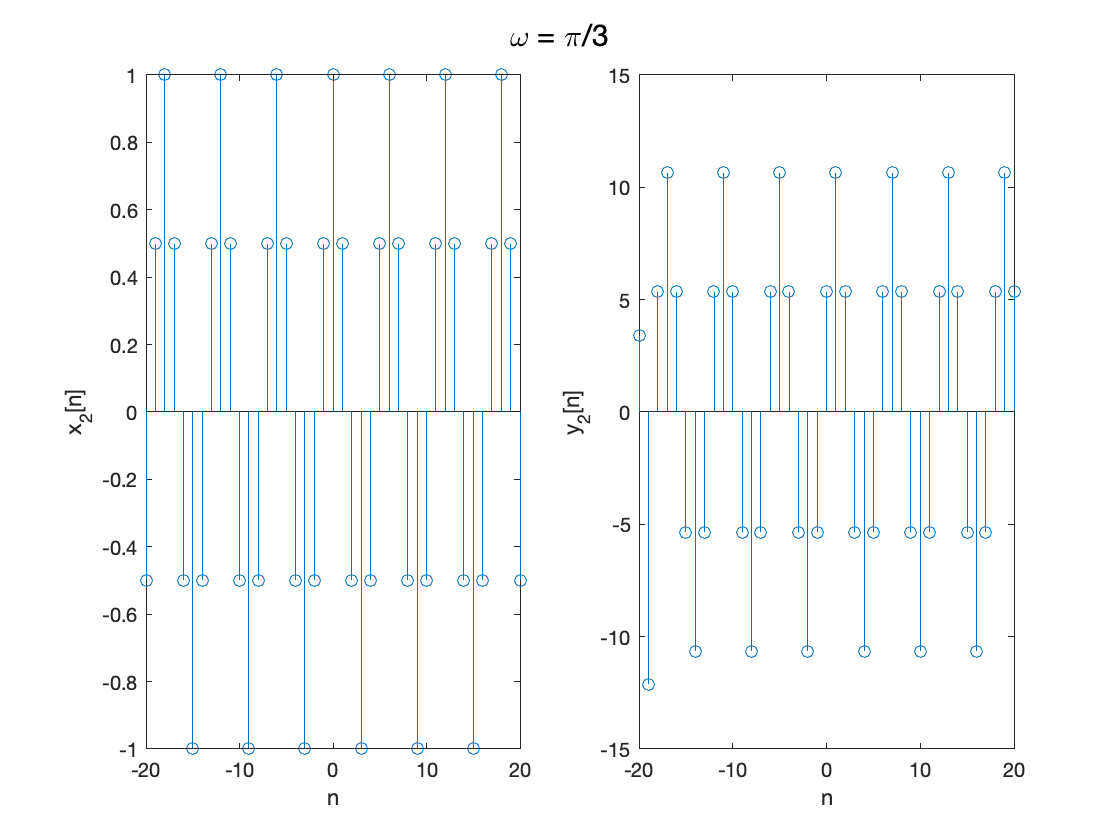

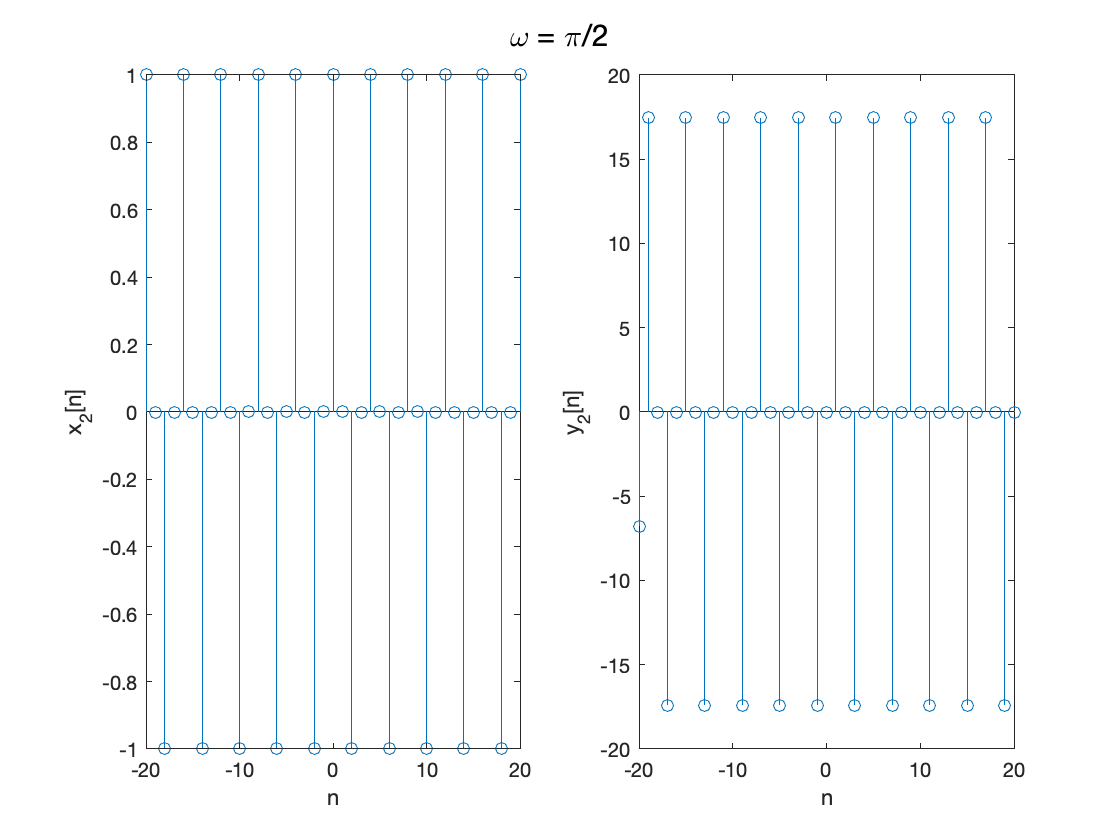

for i = 1:length(omega_values)
    omega = omega_values(i);
    x2n = x2(omega, n);
    y2n = real(dtift(dtft(x2n, n, w) .* Hw, w, n));
    
    figure;
    subplot(1, 2, 1);
    stem(n, x2n);
    xlabel("n"); ylabel("x_2[n]");
    subplot(1, 2, 2);
    stem(n, y2n);
    xlabel("n"); ylabel("y_2[n]");
    sgtitle("\omega = " + omega_val_strings(i));
end

% (b)
